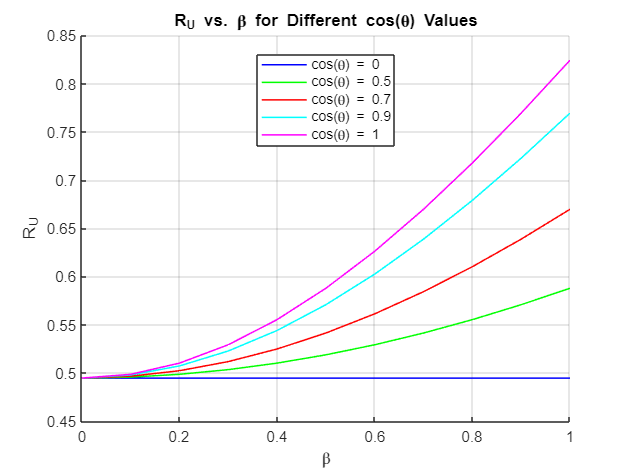

% Parameters
rho = 1;
sigma = 1;
beta_values = 0:0.1:1; % Adjust the range of beta values as needed
cos_theta_values = [0, 0.5, 0.7, 0.9, 1]; % Different values of cos(theta)
R_values = zeros(length(cos_theta_values), length(beta_values));

% Calculate R values
for i = 1:length(cos_theta_values)
    cos_theta = cos_theta_values(i);
    for j = 1:length(beta_values)
        beta = beta_values(j);
        R_values(i, j) = log(1 + (abs(h_BI)^2 * rho + abs(beta * h_BI)^2 * rho * cos_theta^2) / sigma);
    end
end

% Plot
figure;
hold on;
colors = ['b', 'g', 'r', 'c', 'm']; % Different colors for each cos(theta)
linestyle = '-'; % Thin solid line
for i = 1:length(cos_theta_values)
    plot(beta_values, R_values(i, :), linestyle, 'Color', colors(i), 'LineWidth', 1, 'DisplayName', ['cos(\theta) = ' num2str(cos_theta_values(i))]);
end
hold off;
xlabel('\beta');
ylabel('R_U');
title('R_U vs. \beta for Different cos(\theta) Values');
legend('Location', 'Best');
grid on;